# ece 278c hw8 short baseline

## (1) setup

% params
lambda = 1;
Tx = [0, 0];
D = 8*lambda;
R1 = [Tx(1) - D, 0];
R2 = [Tx(1) + D, 0];
R1m = [Tx(1) - D/2, 0];
R2m = [Tx(1) + D/2, 0];
p = [9*lambda, 15*lambda];
N = 128; % number of fmcw frequencies
berth = 10*lambda;
xlim = [p(1)-berth p(1)+berth]; % target region specs
ylim = [p(2)-berth p(2)+berth];
spacing = lambda/8;

% to capture the whole region
xlim = [-30*lambda 30*lambda];
ylim = [-30*lambda 30*lambda];
spacing = lambda/4;

r0 = sqrt((p(1)-Tx(1))^2+(p(2)-Tx(2))^2);
r1 = sqrt((p(1)-R1(1))^2+(p(2)-R1(2))^2);
r2 = sqrt((p(1)-R2(1))^2+(p(2)-R2(2))^2);

% create array of wavelengths
wavelengths = zeros([1 N]);
for n = 1:N
    wavelengths(n) = N/(n + N/2);
end

## (2) gather data

R1data = zeros([1 N]);
R2data = zeros([1 N]);
for i = 1:N
    lambda = wavelengths(i);
    % R1data(i) = (1j*lambda*r)^-0.5*exp(-1j*pi*r/lambda)
    R1data(i) = exp(1j*pi*(r0+r1)/lambda);
    R2data(i) = exp(1j*pi*(r0+r2)/lambda);
end

## (3) active bistatic (hw7)

h_tot = zeros(0);
spectrum_tot = zeros(0);
for i = 1:N
    [x1,y1,h1,spectrum1,fx1] = reconstruct(wavelengths(1:i),spacing,spacing,xlim,ylim,R1,Tx,R1data);
    [x2,y2,h2,spectrum2,fx2] = reconstruct(wavelengths(1:i),spacing,spacing,xlim,ylim,R2,Tx,R2data);
    h_tot = [h_tot; h1+h2];
    spectrum_tot = [spectrum_tot; spectrum1+spectrum2];
    disp(string(round(100*i/N,2))+' %');
end

0.78 %
1.56 %
2.34 %
3.13 %
3.91 %
4.69 %
5.47 %
6.25 %
7.03 %
7.81 %
8.59 %
9.38 %
10.16 %
10.94 %
11.72 %
12.5 %
13.28 %
14.06 %
14.84 %
15.63 %
16.41 %
17.19 %
17.97 %
18.75 %
19.53 %
20.31 %
21.09 %
21.88 %
22.66 %
23.44 %
24.22 %
25 %
25.78 %
26.56 %
27.34 %
28.13 %
28.91 %
29.69 %
30.47 %
31.25 %
32.03 %
32.81 %
33.59 %
34.38 %
35.16 %
35.94 %
36.72 %
37.5 %
38.28 %
39.06 %
39.84 %
40.63 %
41.41 %
42.19 %
42.97 %
43.75 %
44.53 %
45.31 %
46.09 %
46.88 %
47.66 %
48.44 %
49.22 %
50 %
50.78 %
51.56 %
52.34 %
53.13 %
53.91 %
54.69 %
55.47 %
56.25 %
57.03 %
57.81 %
58.59 %
59.38 %
60.16 %
60.94 %
61.72 %
62.5 %
63.28 %
64.06 %
64.84 %
65.63 %
66.41 %
67.19 %
67.97 %
68.75 %
69.53 %
70.31 %
71.09 %
71.88 %
72.66 %
73.44 %
74.22 %
75 %
75.78 %
76.56 %
77.34 %
78.13 %
78.91 %
79.69 %
80.47 %
81.25 %
82.03 %
82.81 %
83.59 %
84.38 %
85.16 %
85.94 %
86.72 %
87.5 %
88.28 %
89.06 %
89.84 %
90.63 %
91.41 %
92.19 %
92.97 %
93.75 %
94.53 %
95.31 %
96.09 %
96.88 %
97.66 %
98.44 %
99.22 %
100 %


## active monostatic (hw 8.1)

h_tot_81 = zeros(0);
spectrum_tot_81 = zeros(0);
for i = 1:N
    [x1,y1,h1,spectrum1,fx1] = reconstruct(wavelengths(1:i),spacing,spacing,xlim,ylim,R1m,R1m,R1data);
    [x2,y2,h2,spectrum2,fx2] = reconstruct(wavelengths(1:i),spacing,spacing,xlim,ylim,R2m,R2m,R2data);
    h_tot_81 = [h_tot_81; h1+h2];
    spectrum_tot_81 = [spectrum_tot_81; spectrum1+spectrum2];
    disp(string(round(100*i/N,2))+' %');
end

0.78 %
1.56 %
2.34 %
3.13 %
3.91 %
4.69 %
5.47 %
6.25 %
7.03 %
7.81 %
8.59 %
9.38 %
10.16 %
10.94 %
11.72 %
12.5 %
13.28 %
14.06 %
14.84 %
15.63 %
16.41 %
17.19 %
17.97 %
18.75 %
19.53 %
20.31 %
21.09 %
21.88 %
22.66 %
23.44 %
24.22 %
25 %
25.78 %
26.56 %
27.34 %
28.13 %
28.91 %
29.69 %
30.47 %
31.25 %
32.03 %
32.81 %
33.59 %
34.38 %
35.16 %
35.94 %
36.72 %
37.5 %
38.28 %
39.06 %
39.84 %
40.63 %
41.41 %
42.19 %
42.97 %
43.75 %
44.53 %
45.31 %
46.09 %
46.88 %
47.66 %
48.44 %
49.22 %
50 %
50.78 %
51.56 %
52.34 %
53.13 %
53.91 %
54.69 %
55.47 %
56.25 %
57.03 %
57.81 %
58.59 %
59.38 %
60.16 %
60.94 %
61.72 %
62.5 %
63.28 %
64.06 %
64.84 %
65.63 %
66.41 %
67.19 %
67.97 %
68.75 %
69.53 %
70.31 %
71.09 %
71.88 %
72.66 %
73.44 %
74.22 %
75 %
75.78 %
76.56 %
77.34 %
78.13 %
78.91 %
79.69 %
80.47 %
81.25 %
82.03 %
82.81 %
83.59 %
84.38 %
85.16 %
85.94 %
86.72 %
87.5 %
88.28 %
89.06 %
89.84 %
90.63 %
91.41 %
92.19 %
92.97 %
93.75 %
94.53 %
95.31 %
96.09 %
96.88 %
97.66 %
98.44 %
99.22 %
100 %


## range and bearing angle (hw 8.2)

h_tot_82 = zeros(0);
spectrum_tot_82 = zeros(0);
Rrdata = R1data.*R2data;
Rbdata = R1data.*conj(R2data);
for i = 1:N
    [x1,y1,h1,spectrum1,fx1] = reconstruct(wavelengths(1:i),spacing,spacing,xlim,ylim,Tx,Tx,Rrdata,'range');
    [x2,y2,h2,spectrum2,fx2] = reconstruct(wavelengths(1:i),spacing,spacing,xlim,ylim,R1,R2,Rbdata,'bearing angle');
    h_tot_82 = [h_tot_82; h1+h2];
    spectrum_tot_82 = [spectrum_tot_82; spectrum1+spectrum2];
    disp(string(round(100*i/N,2))+' %');
end

0.78 %
1.56 %
2.34 %
3.13 %
3.91 %
4.69 %
5.47 %
6.25 %
7.03 %
7.81 %
8.59 %
9.38 %
10.16 %
10.94 %
11.72 %
12.5 %
13.28 %
14.06 %
14.84 %
15.63 %
16.41 %
17.19 %
17.97 %
18.75 %
19.53 %
20.31 %
21.09 %
21.88 %
22.66 %
23.44 %
24.22 %
25 %
25.78 %
26.56 %
27.34 %
28.13 %
28.91 %
29.69 %
30.47 %
31.25 %
32.03 %
32.81 %
33.59 %
34.38 %
35.16 %
35.94 %
36.72 %
37.5 %
38.28 %
39.06 %
39.84 %
40.63 %
41.41 %
42.19 %
42.97 %
43.75 %
44.53 %
45.31 %
46.09 %
46.88 %
47.66 %
48.44 %
49.22 %
50 %
50.78 %
51.56 %
52.34 %
53.13 %
53.91 %
54.69 %
55.47 %
56.25 %
57.03 %
57.81 %
58.59 %
59.38 %
60.16 %
60.94 %
61.72 %
62.5 %
63.28 %
64.06 %
64.84 %
65.63 %
66.41 %
67.19 %
67.97 %
68.75 %
69.53 %
70.31 %
71.09 %
71.88 %
72.66 %
73.44 %
74.22 %
75 %
75.78 %
76.56 %
77.34 %
78.13 %
78.91 %
79.69 %
80.47 %
81.25 %
82.03 %
82.81 %
83.59 %
84.38 %
85.16 %
85.94 %
86.72 %
87.5 %
88.28 %
89.06 %
89.84 %
90.63 %
91.41 %
92.19 %
92.97 %
93.75 %
94.53 %
95.31 %
96.09 %
96.88 %
97.66 %
98.44 %
99.22 %
100 %


## polar format (hw 8.3)

Rrdata = R1data.*R2data;
Rbdata = R1data.*conj(R2data);

Nfft = N;
scale_factor = round(N/(2*D));
Nfft_scale = Nfft*scale_factor;
rr = zeros([N Nfft]);
bb = zeros([N Nfft_scale]);
for i = 1:N
    rr(i,:) = abs(fft(Rrdata(1:i),Nfft));
    bb(i,:) = abs(fft(Rbdata(1:i),Nfft_scale));
end

domain = [1:D*scale_factor+1 Nfft_scale-D*scale_factor+1:Nfft_scale];

x3 = zeros(0);
y3 = zeros(0);
h_tot_83 = zeros(0);
for k = 1:N
    h83 = zeros(0);
    for i = 1:length(domain)
        for j = 1:Nfft
            if k == 1
                if domain(i) > Nfft_scale/2
                    x3 = [x3; -(Nfft_scale-(domain(i)-1))*90/(scale_factor*D)];
                else
                    x3 = [x3; (domain(i)-1)*90/(scale_factor*D)];
                end
                y3 = [y3; (j-1)/2];
            end
            h83 = [h83 bb(k,domain(i))+rr(k,j)];
        end
    end
    h_tot_83 = [h_tot_83; h83];
    disp(string(round(100*k/N,2))+' %');
end

0.78 %
1.56 %
2.34 %
3.13 %
3.91 %
4.69 %
5.47 %
6.25 %
7.03 %
7.81 %
8.59 %
9.38 %
10.16 %
10.94 %
11.72 %
12.5 %
13.28 %
14.06 %
14.84 %
15.63 %
16.41 %
17.19 %
17.97 %
18.75 %
19.53 %
20.31 %
21.09 %
21.88 %
22.66 %
23.44 %
24.22 %
25 %
25.78 %
26.56 %
27.34 %
28.13 %
28.91 %
29.69 %
30.47 %
31.25 %
32.03 %
32.81 %
33.59 %
34.38 %
35.16 %
35.94 %
36.72 %
37.5 %
38.28 %
39.06 %
39.84 %
40.63 %
41.41 %
42.19 %
42.97 %
43.75 %
44.53 %
45.31 %
46.09 %
46.88 %
47.66 %
48.44 %
49.22 %
50 %
50.78 %
51.56 %
52.34 %
53.13 %
53.91 %
54.69 %
55.47 %
56.25 %
57.03 %
57.81 %
58.59 %
59.38 %
60.16 %
60.94 %
61.72 %
62.5 %
63.28 %
64.06 %
64.84 %
65.63 %
66.41 %
67.19 %
67.97 %
68.75 %
69.53 %
70.31 %
71.09 %
71.88 %
72.66 %
73.44 %
74.22 %
75 %
75.78 %
76.56 %
77.34 %
78.13 %
78.91 %
79.69 %
80.47 %
81.25 %
82.03 %
82.81 %
83.59 %
84.38 %
85.16 %
85.94 %
86.72 %
87.5 %
88.28 %
89.06 %
89.84 %
90.63 %
91.41 %
92.19 %
92.97 %
93.75 %
94.53 %
95.31 %
96.09 %
96.88 %
97.66 %
98.44 %
99.22 %
100 %


% convert polar to cartesian
x3c = zeros(size(x3));
y3c = zeros(size(y3));
for i = 1:length(x3c)
    theta = x3(i);
    r = y3(i);
    x3c(i) = r*cos((90-theta)*pi/180);
    y3c(i) = r*sin((90-theta)*pi/180);
end

## test each method

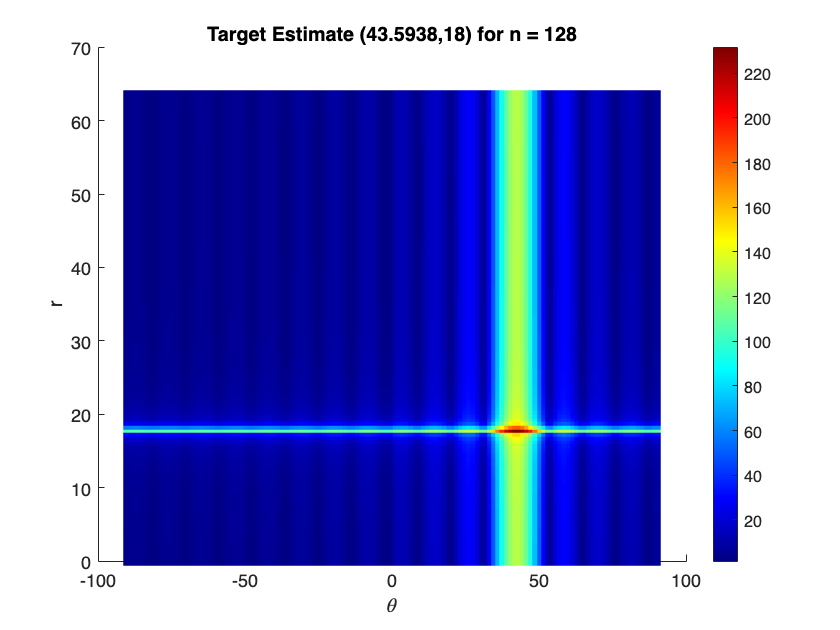

[mag,index] = max(h_tot_83(N,:));
target_estimate = [x3(index),y3(index)];
figure;
scatter(x3,y3,50,abs(h_tot_83(N,:)),'square','filled')
fontsize(12,"points")
title('Target Estimate ('+string(target_estimate(1))+','+string(target_estimate(2))+ ') for n = '+string(N))
xlabel('\theta'); ylabel('r');
colormap(jet)
colorbar

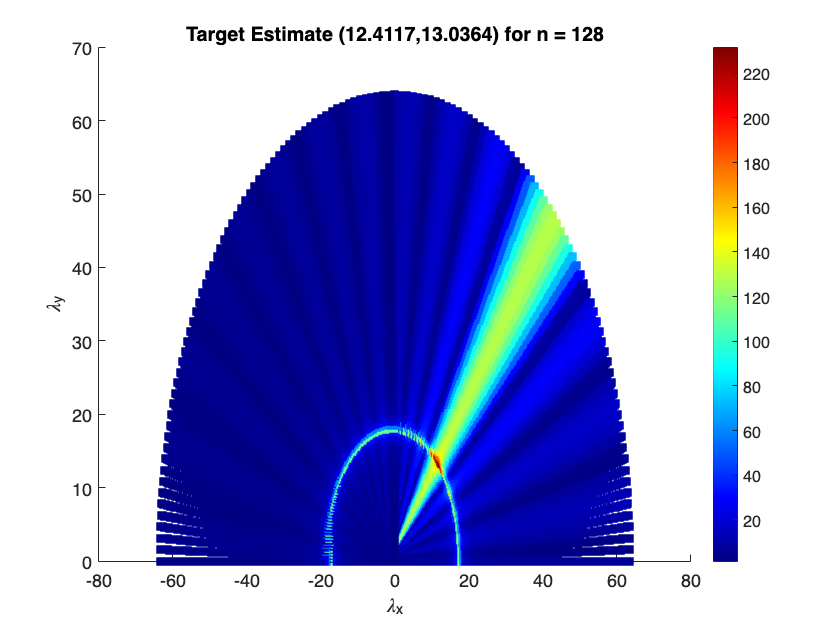

target_estimate = [x3c(index),y3c(index)];
figure;
scatter(x3c,y3c,50,abs(h_tot_83(N,:)),'square','filled')
fontsize(12,"points")
title('Target Estimate ('+string(target_estimate(1))+','+string(target_estimate(2))+ ') for n = '+string(N))
xlabel('\lambda_x'); ylabel('\lambda_y');
colormap(jet)
colorbar

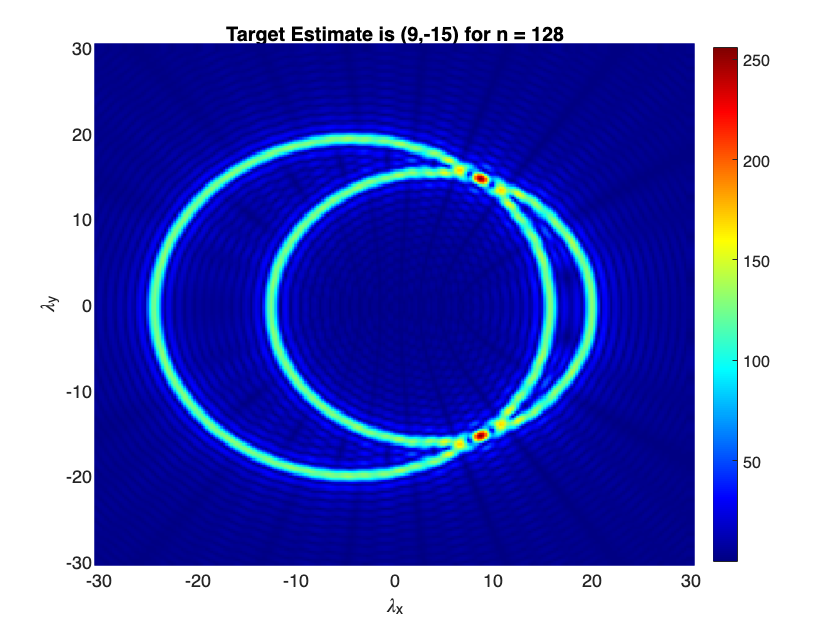

[mag,index] = max(h_tot(N,:));
target_estimate = [x1(index),y1(index)];
figure;
scatter(x1,y1,50,abs(h_tot(N,:)),'square','filled')
fontsize(12,"points")
title('Target Estimate is ('+string(target_estimate(1))+','+string(target_estimate(2))+ ') for n = '+string(N))
xlabel('\lambda_x'); ylabel('\lambda_y');
colormap(jet)
colorbar

% figure;
% start_index = 1+((N-1)*size(spectrum_tot,2));
% spec = abs(fftshift(spectrum_tot(start_index:start_index+size(spectrum_tot,2)-1,:)));
% ht = size(spec,1); wt = size(spec,2); d = length(fx1);
% % imagesc(fx1(1,d/4:3*d/4),fx1(1,d/4:3*d/4),spec(ht/4:ht*3/4,wt/4:wt*3/4));
% imagesc(fx1,fx1,spec);
% fontsize(12,"points")
% title('Spectrum  n = ' + string(i)')
% xlabel('$\lambda_x$','Interpreter','latex');
% ylabel('$\lambda_y$','Interpreter','latex');
% colormap(jet)

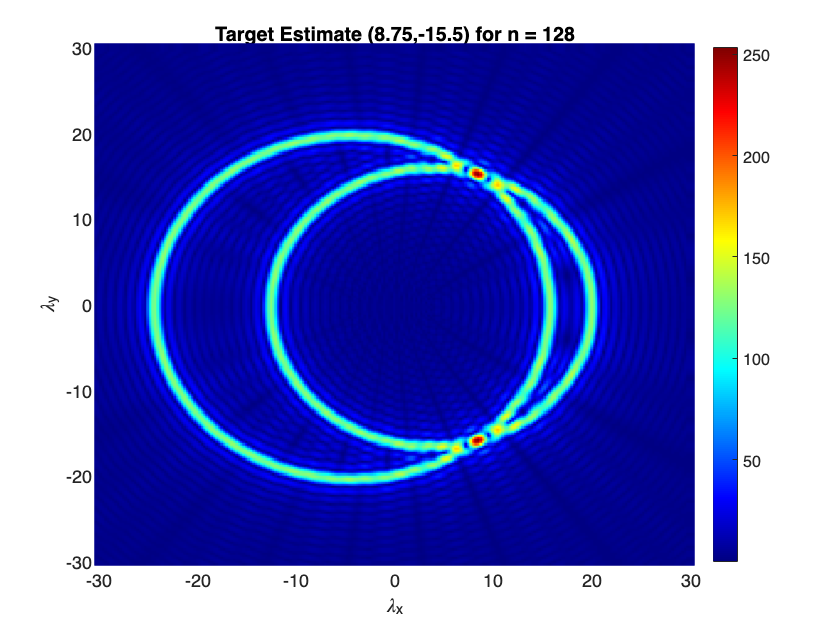

[mag,index] = max(h_tot_81(N,:));
target_estimate = [x1(index),y1(index)];
figure;
scatter(x1,y1,50,abs(h_tot_81(N,:)),'square','filled')
fontsize(12,"points")
title('Target Estimate ('+string(target_estimate(1))+','+string(target_estimate(2))+ ') for n = '+string(N))
xlabel('\lambda_x'); ylabel('\lambda_y');
colormap(jet)
colorbar

% figure;
% start_index = 1+((N-1)*size(spectrum_tot_81,2));
% spec = abs(fftshift(spectrum_tot_81(start_index:start_index+size(spectrum_tot_81,2)-1,:)));
% ht = size(spec,1); wt = size(spec,2); d = length(fx1);
% % imagesc(fx1(1,d/4:3*d/4),fx1(1,d/4:3*d/4),spec(ht/4:ht*3/4,wt/4:wt*3/4));
% imagesc(fx1,fx1,spec);
% fontsize(12,"points")
% title('Spectrum  n = ' + string(i)')
% xlabel('$\lambda_x$','Interpreter','latex');
% ylabel('$\lambda_y$','Interpreter','latex');
% colormap(jet)

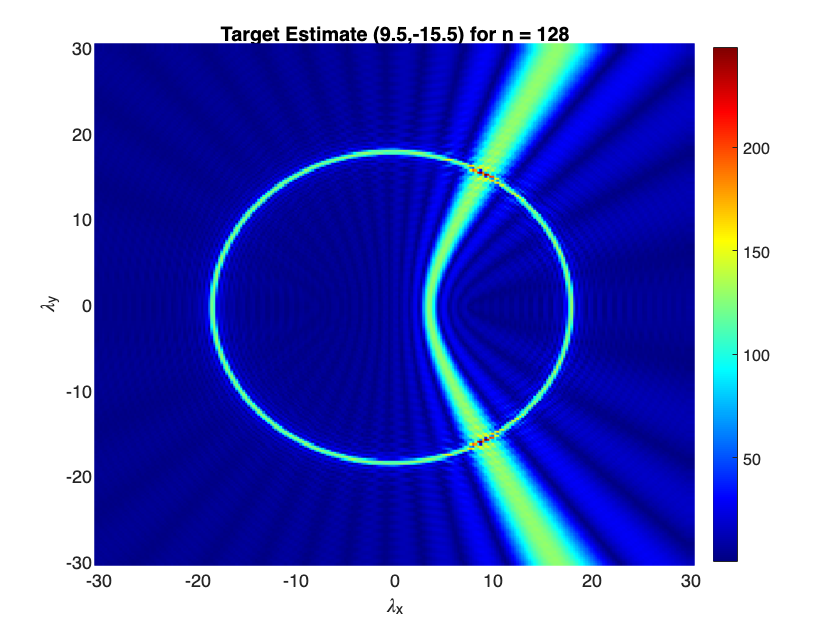

[mag,index] = max(h_tot_82(N,:));
target_estimate = [x1(index),y1(index)];
figure;
scatter(x1,y1,50,abs(h_tot_82(N,:)),'square','filled')
fontsize(12,"points")
title('Target Estimate ('+string(target_estimate(1))+','+string(target_estimate(2))+ ') for n = '+string(N))
xlabel('\lambda_x'); ylabel('\lambda_y');
colormap(jet)
colorbar

% figure;
% start_index = 1+((N-1)*size(spectrum_tot_82,2));
% spec = abs(fftshift(spectrum_tot_82(start_index:start_index+size(spectrum_tot_82,2)-1,:)));
% ht = size(spec,1); wt = size(spec,2); d = length(fx1);
% % imagesc(fx1(1,d/4:3*d/4),fx1(1,d/4:3*d/4),spec(ht/4:ht*3/4,wt/4:wt*3/4));
% imagesc(fx1,fx1,spec);
% fontsize(12,"points")
% title('Spectrum  n = ' + string(i)')
% xlabel('$\lambda_x$','Interpreter','latex');
% ylabel('$\lambda_y$','Interpreter','latex');
% colormap(jet)

## (4) save wavefield and spectra as jpg images

cd ..; cd images83p;

for i = 1:N
    % plot wavefield
    f = figure('visible','off');
    scatter(x3,y3,50,abs(h_tot_83(i,:)),'square','filled')
    [mag,index] = max(h_tot_83(i,:));
    target_estimate = [x3(index),y3(index)];
    fontsize(12,"points")
    title('Target Estimate is (' +string(target_estimate(1))+','+string(target_estimate(2))+ ') for n = '+string(i))
    xlabel('\theta (deg)'); ylabel('r');
    colormap(jet)
    colorbar
    saveas(f,'space_n'+string(i),'jpg');
    % % plot spectrum
    % start_index = 1+((i-1)*size(spectrum_tot,2));
    % spec = abs(fftshift(spectrum_tot(start_index:start_index+size(spectrum_tot,2)-1,:)));
    % ht = size(spec,1); wt = size(spec,2); d = length(fx1);
    % % imagesc(fx1(1,d/4:3*d/4),fx1(1,d/4:3*d/4),spec(ht/4:ht*3/4,wt/4:wt*3/4));
    % imagesc(fx1,fx1,spec);
    % fontsize(12,"points")
    % title('Spectrum  n = ' + string(i)')
    % xlabel('$3\lambda_x/2$','Interpreter','latex');
    % ylabel('$3\lambda_y/2$','Interpreter','latex');
    % colormap(jet)
    % colorbar
    % saveas(f,'freq_n'+string(i),'jpg');
    disp('n = ' + string(i) + ' of ' + string(N))
end

n = 1 of 128
n = 2 of 128
n = 3 of 128
n = 4 of 128
n = 5 of 128
n = 6 of 128
n = 7 of 128
n = 8 of 128
n = 9 of 128
n = 10 of 128
n = 11 of 128
n = 12 of 128
n = 13 of 128
n = 14 of 128
n = 15 of 128
n = 16 of 128
n = 17 of 128
n = 18 of 128
n = 19 of 128
n = 20 of 128
n = 21 of 128
n = 22 of 128
n = 23 of 128
n = 24 of 128
n = 25 of 128
n = 26 of 128
n = 27 of 128
n = 28 of 128
n = 29 of 128
n = 30 of 128
n = 31 of 128
n = 32 of 128
n = 33 of 128
n = 34 of 128
n = 35 of 128
n = 36 of 128
n = 37 of 128
n = 38 of 128
n = 39 of 128
n = 40 of 128
n = 41 of 128
n = 42 of 128
n = 43 of 128
n = 44 of 128
n = 45 of 128
n = 46 of 128
n = 47 of 128
n = 48 of 128
n = 49 of 128
n = 50 of 128
n = 51 of 128
n = 52 of 128
n = 53 of 128
n = 54 of 128
n = 55 of 128
n = 56 of 128
n = 57 of 128
n = 58 of 128
n = 59 of 128
n = 60 of 128
n = 61 of 128
n = 62 of 128
n = 63 of 128
n = 64 of 128
n = 65 of 128
n = 66 of 128
n = 67 of 128
n = 68 of 128
n = 69 of 128
n = 70 of 128
n = 71 of 128
n = 72 of 128
n

## (5) create the videos

framerate = 16; % frames per second
type = '83p_(9,15)';

% load the images
wavefields = cell(N,1);
%spectra = cell(N,1);
for i = 1:N
    wavefields{i} = imread('space_n'+string(i)+'.jpg'); 
    %spectra{i} = imread('freq_n'+string(i)+'.jpg'); 
end

% create the videos
cd ..; cd videos;
space_vid = VideoWriter('hw'+string(type)+'.mp4','MPEG-4');
%freq_vid = VideoWriter('spectra_'+string(type)+'.mp4','MPEG-4'); 
space_vid.FrameRate = framerate;
%freq_vid.FrameRate = framerate;

open(space_vid); 
for i = 1:N
	wavefield = im2frame(wavefields{i});
	writeVideo(space_vid, wavefield);
end

close(space_vid); 

% open(freq_vid); 
% for i = 1:N
%     spectrum = im2frame(spectra{i});
%     writeVideo(freq_vid, spectrum);
% end
% close(freq_vid); 
cd ..; cd code;

## (6) accuracy analysis

% separation distance
DD = 1:20;
err_sd = zeros([4 length(DD)]);
for i = 1:length(DD)
    [x,y,h7,h81,h82,x83,y83,h83] = estimate(p,DD(i),N);
    [~,idx7] = max(h7);
    [~,idx81] = max(h81);
    [~,idx82] = max(h82);
    [~,idx83] = max(h83);
    err_7 = sqrt((x(idx7)-p(1))^2 + (y(idx7)-p(2))^2);
    err_81 = sqrt((x(idx81)-p(1))^2 + (y(idx81)-p(2))^2);
    err_82 = sqrt((x(idx82)-p(1))^2 + (y(idx82)-p(2))^2);
    err_83 = sqrt((x83(2,idx83)-p(1))^2 + (y83(2,idx83)-p(2))^2);
    err_sd(:,i) = [err_7; err_81; err_82; err_83];
    disp(string(100*i/length(DD))+' %');
end

5 %
10 %
15 %
20 %
25 %
30 %
35 %
40 %
45 %
50 %
55 %
60 %
65 %
70 %
75 %
80 %
85 %
90 %
95 %
100 %


% number of wavelengths
NN = 16:128;
err_w = zeros([4 length(NN)]);
for i = 1:length(NN)
    [x,y,h7,h81,h82,x83,y83,h83] = estimate(p,D,NN(i));
    [~,idx7] = max(h7);
    [~,idx81] = max(h81);
    [~,idx82] = max(h82);
    [~,idx83] = max(h83);
    err_7 = sqrt((x(idx7)-p(1))^2 + (y(idx7)-p(2))^2);
    err_81 = sqrt((x(idx81)-p(1))^2 + (y(idx81)-p(2))^2);
    err_82 = sqrt((x(idx82)-p(1))^2 + (y(idx82)-p(2))^2);
    err_83 = sqrt((x83(2,idx83)-p(1))^2 + (y83(2,idx83)-p(2))^2);
    err_w(:,i) = [err_7; err_81; err_82; err_83];
    disp(string(100*i/length(NN))+' %');
end

0.88496 %
1.7699 %
2.6549 %
3.5398 %
4.4248 %
5.3097 %
6.1947 %
7.0796 %
7.9646 %
8.8496 %
9.7345 %
10.6195 %
11.5044 %
12.3894 %
13.2743 %
14.1593 %
15.0442 %
15.9292 %
16.8142 %
17.6991 %
18.5841 %
19.469 %
20.354 %
21.2389 %
22.1239 %
23.0088 %
23.8938 %
24.7788 %
25.6637 %
26.5487 %
27.4336 %
28.3186 %
29.2035 %
30.0885 %
30.9735 %
31.8584 %
32.7434 %
33.6283 %
34.5133 %
35.3982 %
36.2832 %
37.1681 %
38.0531 %
38.9381 %
39.823 %
40.708 %
41.5929 %
42.4779 %
43.3628 %
44.2478 %
45.1327 %
46.0177 %
46.9027 %
47.7876 %
48.6726 %
49.5575 %
50.4425 %
51.3274 %
52.2124 %
53.0973 %
53.9823 %
54.8673 %
55.7522 %
56.6372 %
57.5221 %
58.4071 %
59.292 %
60.177 %
61.0619 %
61.9469 %
62.8319 %
63.7168 %
64.6018 %
65.4867 %
66.3717 %
67.2566 %
68.1416 %
69.0265 %
69.9115 %
70.7965 %
71.6814 %
72.5664 %
73.4513 %
74.3363 %
75.2212 %
76.1062 %
76.9912 %
77.8761 %
78.7611 %
79.646 %
80.531 %
81.4159 %
82.3009 %
83.1858 %
84.0708 %
84.9558 %
85.8407 %
86.7257 %
87.6106 %
88.4956 %
89.3805 %
90.2655 

% target distance
TD = 1:50;
err_td = zeros([6 length(TD)]);
angle = atan(p(2)/p(1));
for i = 1:length(TD)
    pp = [TD(i)*cos(angle) TD(i)*sin(angle)];
    [x,y,h7,h81,h82,x83,y83,h83] = estimate(pp,D,N);
    [~,idx7] = max(h7);
    [~,idx81] = max(h81);
    [~,idx82] = max(h82);
    [~,idx83] = max(h83);
    err_7 = sqrt((x(idx7)-pp(1))^2 + (y(idx7)-pp(2))^2);
    err_81 = sqrt((x(idx81)-pp(1))^2 + (y(idx81)-pp(2))^2);
    err_82 = sqrt((x(idx82)-pp(1))^2 + (y(idx82)-pp(2))^2);
    err_83 = sqrt((x83(2,idx83)-pp(1))^2 + (y83(2,idx83)-pp(2))^2);
    err_83pb = x83(1,idx83) - angle*180/pi;
    err_83pr = y83(1,idx83) - TD(i);
    err_td(:,i) = [err_7; err_81; err_82; err_83; err_83pb; err_83pr];
    disp(string(100*i/length(TD))+' %');
end

2 %
4 %
6 %
8 %
10 %
12 %
14 %
16 %
18 %
20 %
22 %
24 %
26 %
28 %
30 %
32 %
34 %
36 %
38 %
40 %
42 %
44 %
46 %
48 %
50 %
52 %
54 %
56 %
58 %
60 %
62 %
64 %
66 %
68 %
70 %
72 %
74 %
76 %
78 %
80 %
82 %
84 %
86 %
88 %
90 %
92 %
94 %
96 %
98 %
100 %


% target bearing angle
TB = 0:2*pi/180:pi;
err_tb = zeros([6 length(TD)]);
distance = sqrt(p(2)^2 + p(1)^2);
for i = 1:length(TB)
    pp = [distance*cos(TB(i)) distance*sin(TB(i))];
    [x,y,h7,h81,h82,x83,y83,h83] = estimate(pp,D,N);
    [~,idx7] = max(h7);
    [~,idx81] = max(h81);
    [~,idx82] = max(h82);
    [~,idx83] = max(h83);
    err_7 = sqrt((x(idx7)-pp(1))^2 + (y(idx7)-pp(2))^2);
    err_81 = sqrt((x(idx81)-pp(1))^2 + (y(idx81)-pp(2))^2);
    err_82 = sqrt((x(idx82)-pp(1))^2 + (y(idx82)-pp(2))^2);
    err_83 = sqrt((x83(2,idx83)-pp(1))^2 + (y83(2,idx83)-pp(2))^2);
    err_83pb = x83(1,idx83) - (90 - TB(i)*180/pi);
    err_83pr = y83(1,idx83) - distance;
    err_tb(:,i) = [err_7; err_81; err_82; err_83; err_83pb; err_83pr];
    disp(string(100*i/length(TB))+' %');
end

1.0989 %
2.1978 %
3.2967 %
4.3956 %
5.4945 %
6.5934 %
7.6923 %
8.7912 %
9.8901 %
10.989 %
12.0879 %
13.1868 %
14.2857 %
15.3846 %
16.4835 %
17.5824 %
18.6813 %
19.7802 %
20.8791 %
21.978 %
23.0769 %
24.1758 %
25.2747 %
26.3736 %
27.4725 %
28.5714 %
29.6703 %
30.7692 %
31.8681 %
32.967 %
34.0659 %
35.1648 %
36.2637 %
37.3626 %
38.4615 %
39.5604 %
40.6593 %
41.7582 %
42.8571 %
43.956 %
45.0549 %
46.1538 %
47.2527 %
48.3516 %
49.4505 %
50.5495 %
51.6484 %
52.7473 %
53.8462 %
54.9451 %
56.044 %
57.1429 %
58.2418 %
59.3407 %
60.4396 %
61.5385 %
62.6374 %
63.7363 %
64.8352 %
65.9341 %
67.033 %
68.1319 %
69.2308 %
70.3297 %
71.4286 %
72.5275 %
73.6264 %
74.7253 %
75.8242 %
76.9231 %
78.022 %
79.1209 %
80.2198 %
81.3187 %
82.4176 %
83.5165 %
84.6154 %
85.7143 %
86.8132 %
87.9121 %
89.011 %
90.1099 %
91.2088 %
92.3077 %
93.4066 %
94.5055 %
95.6044 %
96.7033 %
97.8022 %
98.9011 %
100 %


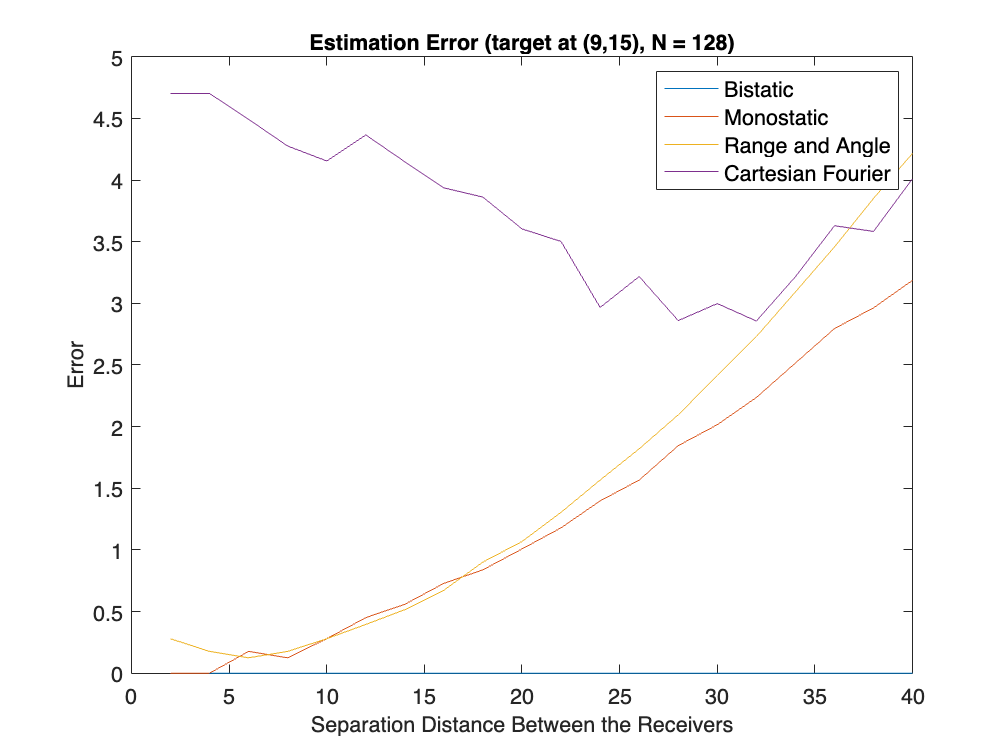

dd = 2.*DD;
plot(dd,err_sd(1,:),dd,err_sd(2,:),dd,err_sd(3,:),dd,err_sd(4,:))
legend('Bistatic','Monostatic','Range and Angle','Cartesian Fourier');
title('Estimation Error (target at (9,15), N = 128)');
xlabel('Separation Distance Between the Receivers'); ylabel('Error');
fontsize(12,'points');

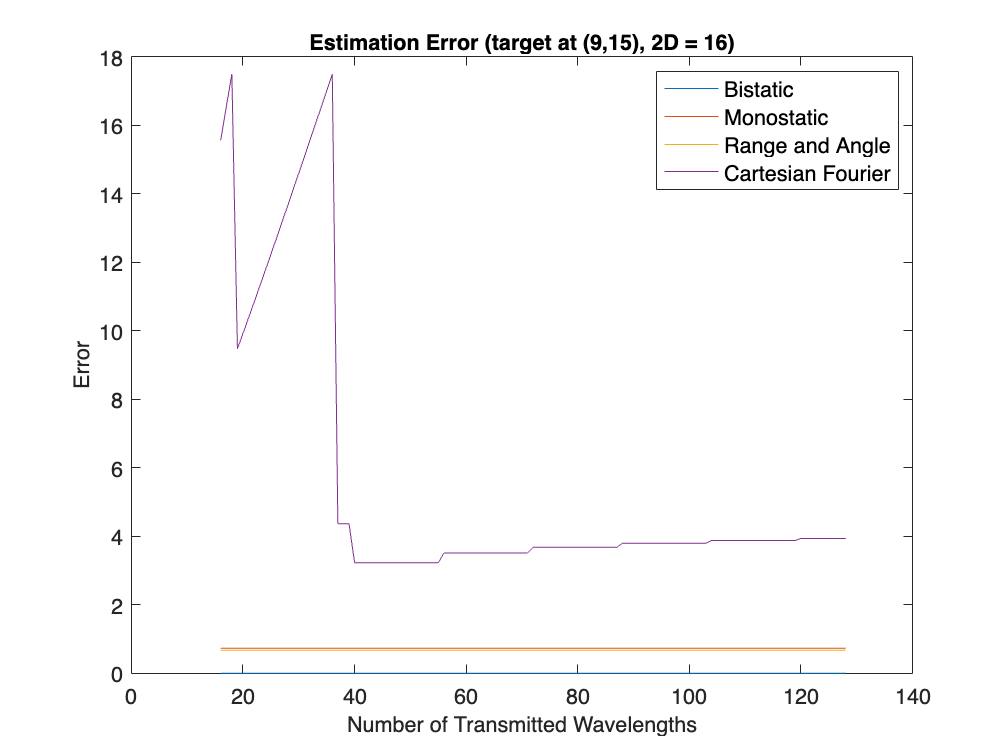

nn = NN;
plot(nn,err_w(1,:),nn,err_w(2,:),nn,err_w(3,:),nn,err_w(4,:))
legend('Bistatic','Monostatic','Range and Angle','Cartesian Fourier');
title('Estimation Error (target at (9,15), 2D = 16)');
xlabel('Number of Transmitted Wavelengths'); ylabel('Error');
fontsize(12,'points');

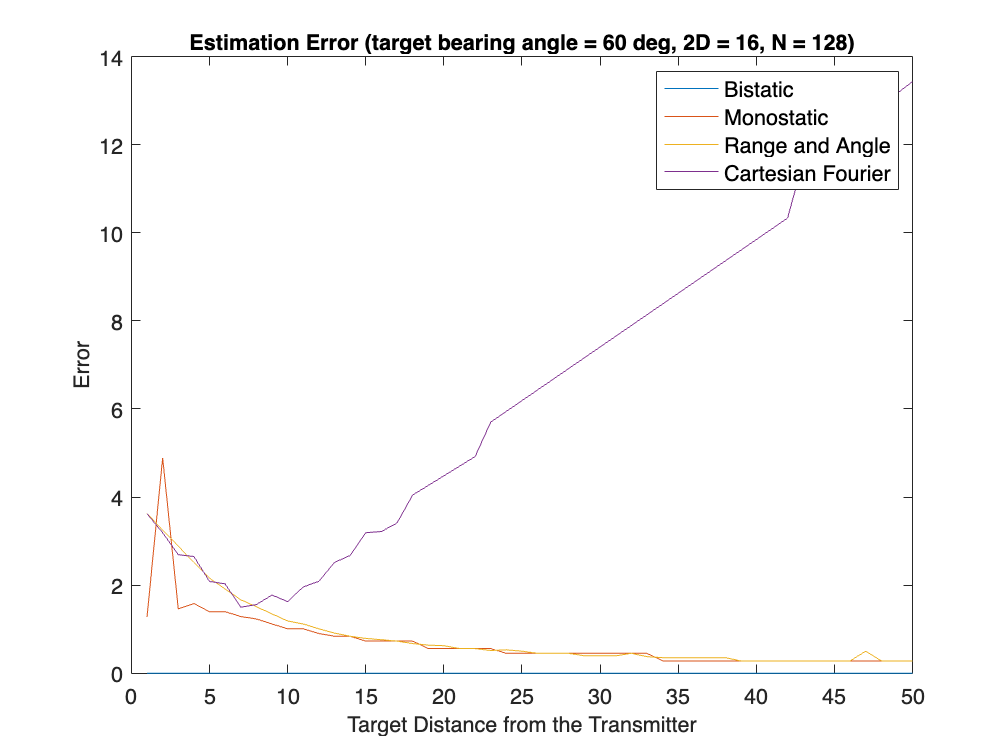

td = TD;
plot(td,err_td(1,:),td,err_td(2,:),td,err_td(3,:),td,err_td(4,:))
legend('Bistatic','Monostatic','Range and Angle','Cartesian Fourier');
title('Estimation Error (target bearing angle = 60 deg, 2D = 16, N = 128)');
xlabel('Target Distance from the Transmitter'); ylabel('Error');
fontsize(12,'points');

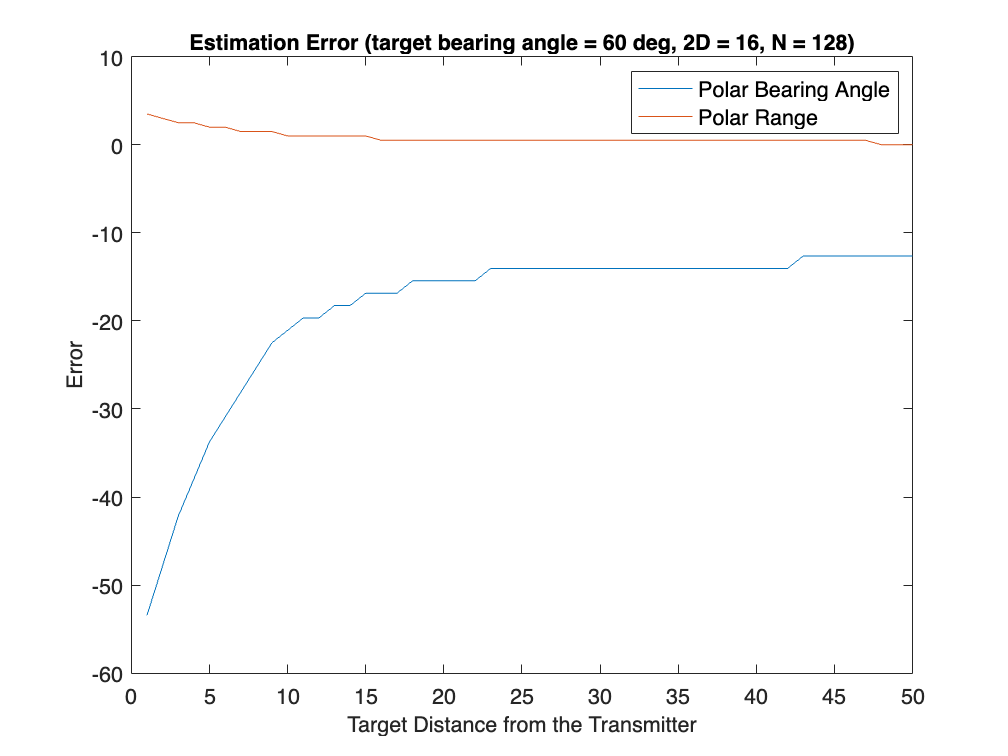

plot(td,err_td(5,:),td,err_td(6,:))
legend('Polar Bearing Angle','Polar Range');
title('Estimation Error (target bearing angle = 60 deg, 2D = 16, N = 128)');
xlabel('Target Distance from the Transmitter'); ylabel('Error');
fontsize(12,'points');

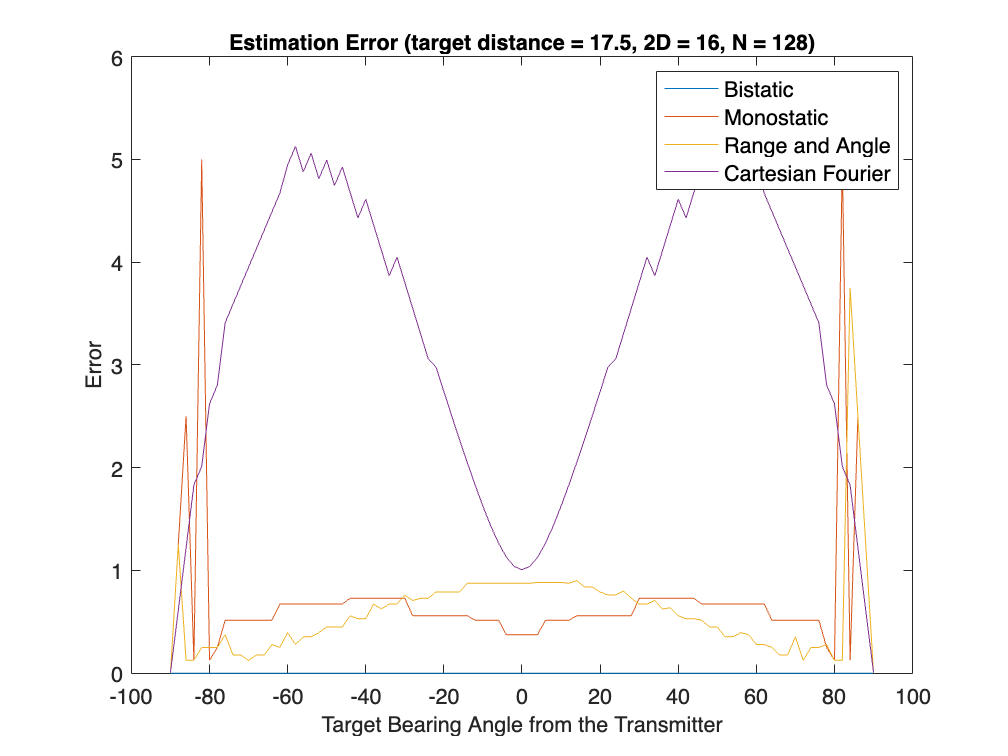

tb = 90 - (TB*180/pi);
plot(tb,err_tb(1,:),tb,err_tb(2,:),tb,err_tb(3,:),tb,err_tb(4,:))
legend('Bistatic','Monostatic','Range and Angle','Cartesian Fourier');
title('Estimation Error (target distance = 17.5, 2D = 16, N = 128)');
xlabel('Target Bearing Angle from the Transmitter'); ylabel('Error');
fontsize(12,'points');

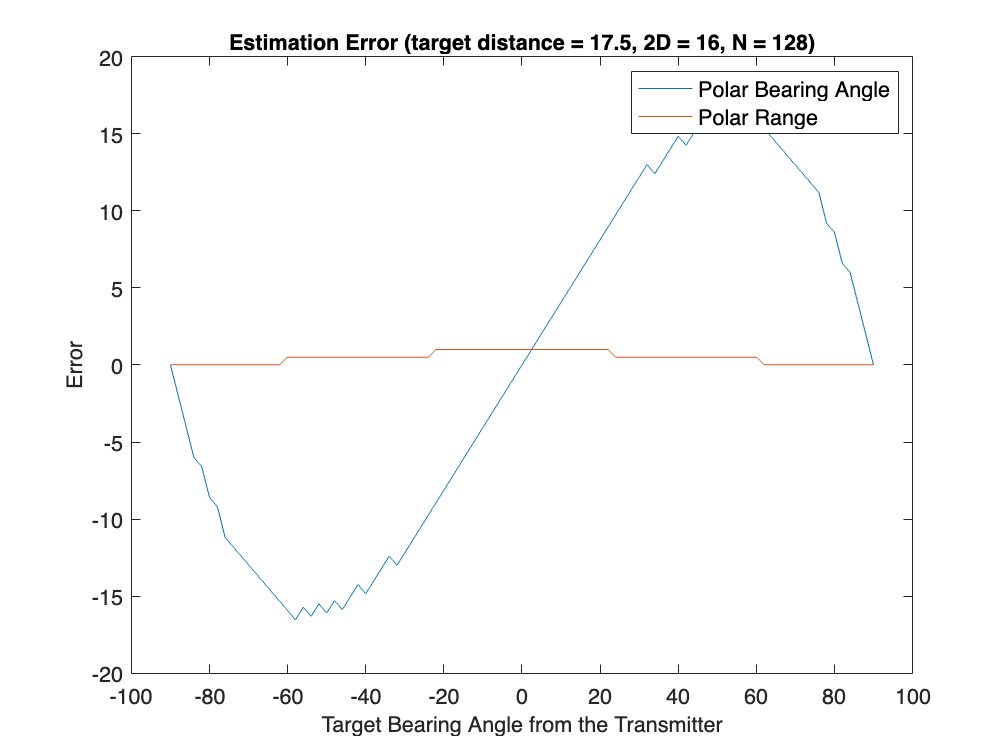

plot(tb,err_tb(5,:),tb,err_tb(6,:))
legend('Polar Bearing Angle','Polar Range');
title('Estimation Error (target distance = 17.5, 2D = 16, N = 128)');
xlabel('Target Bearing Angle from the Transmitter'); ylabel('Error');
fontsize(12,'points');

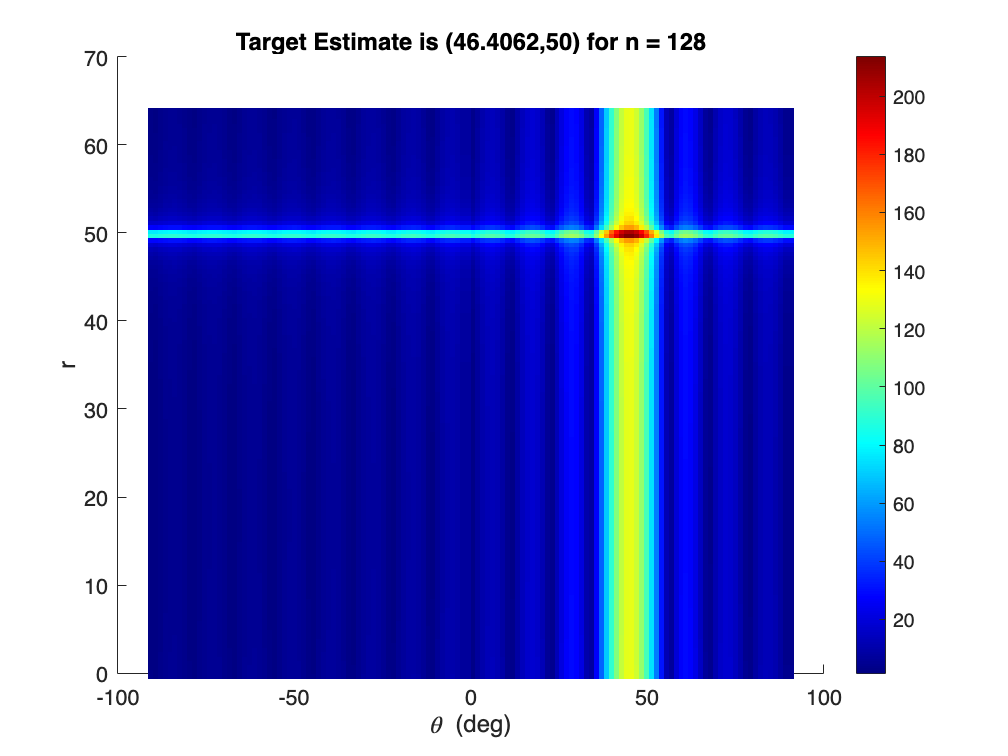

% toggle which estimate to display
figure;
xx = x; yy = y; hh = abs(h7);
%xx = x; yy = y; hh = abs(h81);
%xx = x; yy = y; hh = abs(h82);
%xx = x83(1,:); yy = y83(1,:); hh = abs(h83);
%xx = x83(2,:); yy = y83(2,:); hh = abs(h83);
scatter(xx,yy,60,hh,'square','filled')
[mag,index] = max(hh);
target_estimate = [xx(index),yy(index)];
fontsize(12,"points")
title('Target Estimate is (' +string(target_estimate(1))+','+string(target_estimate(2))+ ') for n = '+string(N))
xlabel('\theta (deg)'); ylabel('r');
colormap(jet)
colorbar